addpath('HHT_EWS')

df_fold = csvread('HHT_EWS/traj_data.csv',1);
df_hopf = csvread('HHT_EWS/traj_data_hopf.csv',1);
df_foldwoNoise = csvread('HHT_EWS/traj_data_fold_woNoise.csv',1);

[imf,residual,info] = emd(df_fold(:,3),'Interpolation','pchip');

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        3     |     0.060257   |  SiftMaxRelativeTolerance
      2      |        3     |      0.10071   |  SiftMaxRelativeTolerance
      3      |        3     |      0.10316   |  SiftMaxRelativeTolerance
      4      |        3     |      0.10175   |  SiftMaxRelativeTolerance
      5      |        3     |     0.097217   |  SiftMaxRelativeTolerance
      6      |        5     |     0.061906   |  SiftMaxRelativeTolerance
      7      |        3     |       0.1114   |  SiftMaxRelativeTolerance
      8      |        2     |      0.19915   |  SiftMaxRelativeTolerance
      9      |        4     |     0.045359   |  SiftMaxRelativeTolerance
     10      |        3     |       0.1131   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


% Perform ensemble EMD
Ne = 500;
sigma_e = 0.5; % still works with sigma = 1.5
rng(50);

avg_trials = [];
for trial_ =1:1:Ne
    noise_ = randn(50000,1).*sigma_e;
    imf_ = emd(df_fold(:,3) + noise_, 'Interpolation', 'pchip');
    
    
    % add on to running avg
    if trial_ == 1
        avg_trials = imf_;
    end
    if trial_ >1
        current_N  = trial_-1;
        avg_trials = avg_trials + imf_;        
    end
end

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031586   |  SiftMaxRelativeTolerance
      2      |        2     |     0.057101   |  SiftMaxRelativeTolerance
      3      |        2     |     0.073184   |  SiftMaxRelativeTolerance
      4      |        2     |     0.072654   |  SiftMaxRelativeTolerance
      5      |        2     |     0.063511   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12268   |  SiftMaxRelativeTolerance
      7      |        2     |      0.11317   |  SiftMaxRelativeTolerance
      8      |        2     |      0.19769   |  SiftMaxRelativeTolerance
      9      |        2     |      0.10706   |  SiftMaxRelativeTolerance
     10      |        3     |      0.07124   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.
Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030707   |  SiftMaxRelativeTolerance


imf_eemd = avg_trials./Ne;

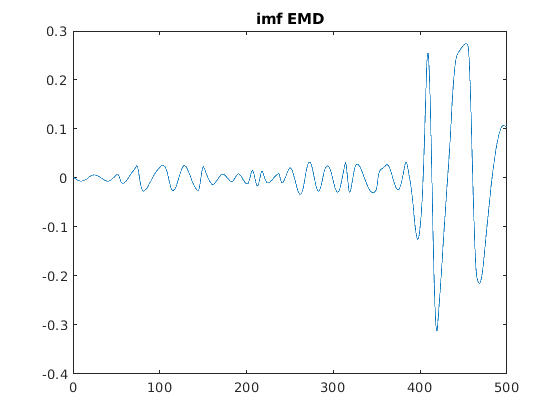

clf
plot(df_fold(:,2), imf(:,9))
title("imf EMD")

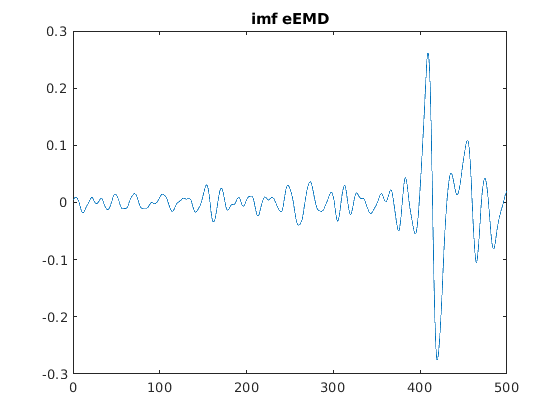

clf
plot(df_fold(:,2), imf_eemd(:,9))
title("imf eEMD")

[hs,f,t,imfinsf,imfinse] = hht(imf,100);
[hs_eemd,f_eemd,t,imfinsf_eemd,imfinse_eemd] = hht(imf_eemd,100);

%t = t(1:40000)

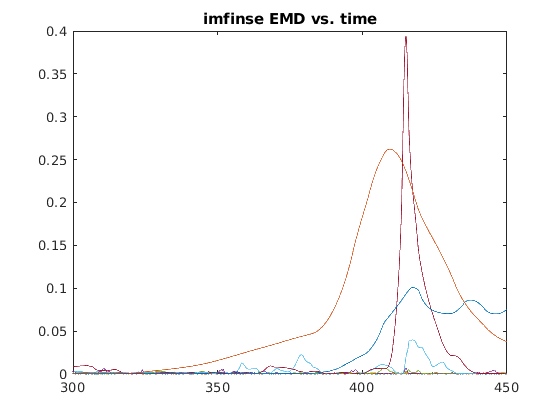

clf
plot(t, imfinse(:,2:end))
title("imfinse EMD vs. time")
xlim([300,450])

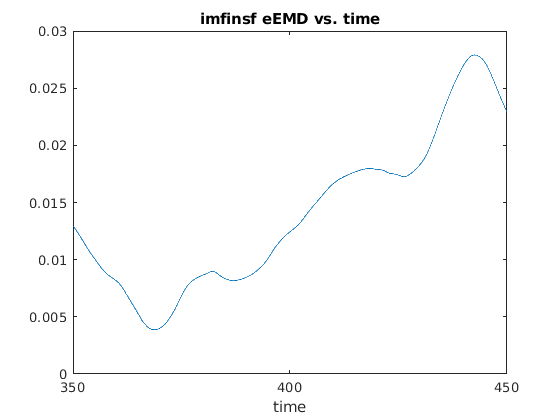

clf
plot(t, imfinsf_eemd(:,10))
title("imfinsf eEMD vs. time")
xlim([350,450])
xlabel("time")

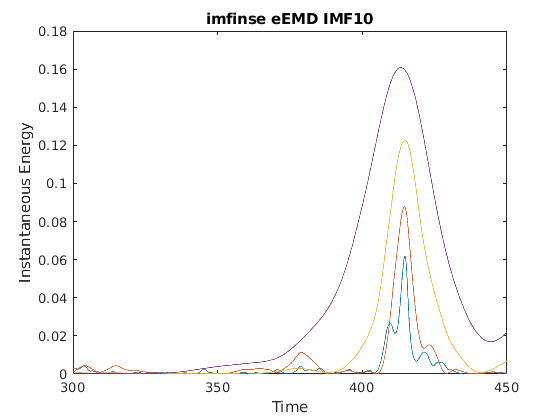

% IMF 10 has a very significant energy increase as 
% the bifurcation is approached
clf 
plot(t, imfinse_eemd(:,7:10))
title("imfinse eEMD IMF10")
xlabel("Time")
ylabel("Instantaneous Energy")
xlim([300,450])

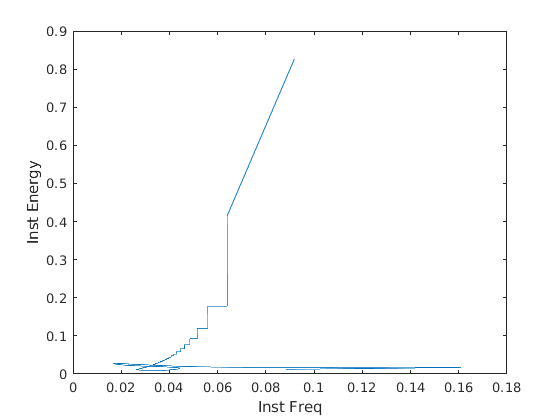

clf 
plot(imfinse_eemd(40000:50000,10), imfinsf_eemd(40000:50000,10))
ylabel("Inst Energy")
xlabel("Inst Freq")

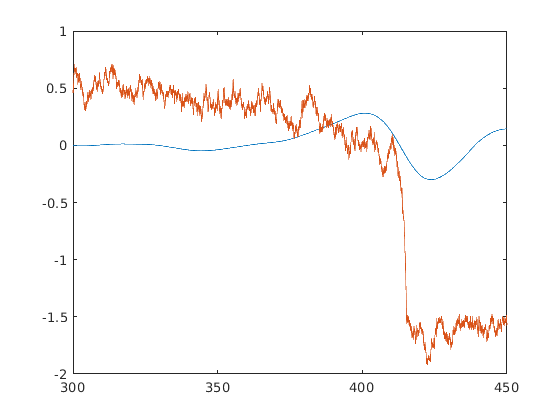

clf
plot(t, imf_eemd(:,10))
hold on
plot(t, df_fold(:,3))
xlim([300,450])

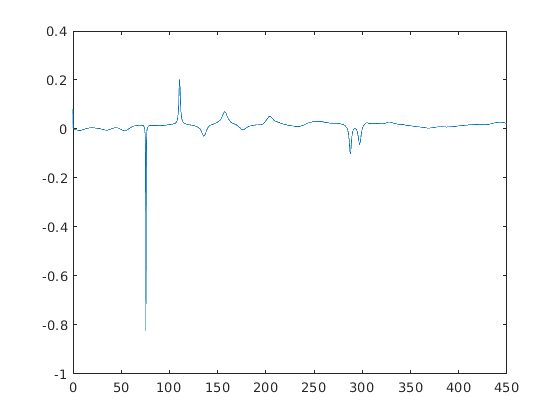

clf
plot(t, imfinsf_eemd(:,10))
xlim([0,450])

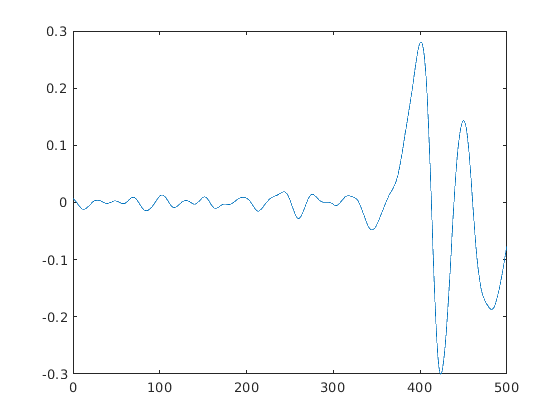

plot(t, imf_eemd(:,10))